# Laboratorio 3 - Modelo diferencial de primer orden

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

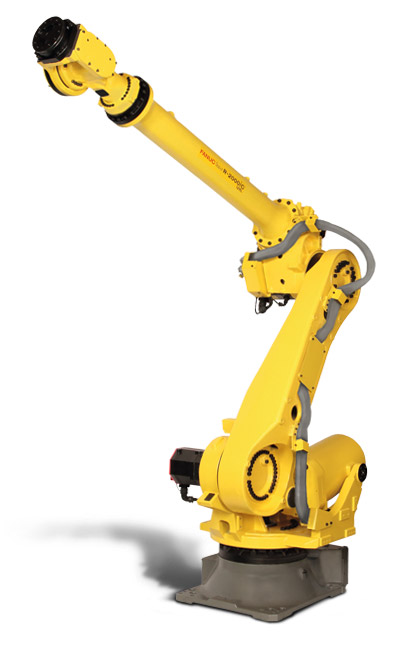

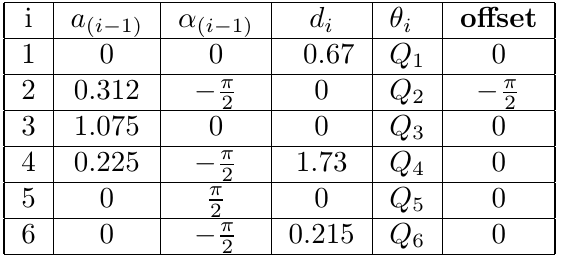

- Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numéricos, NO simbólicos) en función de los ángulos de articulación. 

La de arriba es la tabla de DH mod, para esta lab utilizaremos la DH estándar:

L(1) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0.67, 'offset',0,  ...
    'standard', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',-pi/2,...
    'standard', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',pi/2, 'a', 0,    'd',1.73, 'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',-pi/2,'a', 0,    'd',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',0,    'a', 0,    'd',0.215,'offset',0, ...
    'standard', 'qlim',[-pi pi]);

Robot = SerialLink(L,'name','R_{Fanuc}')

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, stdDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|      0.312|     -1.571|          0|
|  2|         q2|          0|      1.075|          0|     -1.571|
|  3|         q3|          0|      0.225|     -1.571|          0|
|  4|         q4|       1.73|          0|      1.571|          0|
|  5|         q5|          0|          0|     -1.571|          0|
|  6|         q6|      0.215|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            


%Posición de las articulaciones del robot
q = [0 pi/2 0 -pi/2 0 0];

A_0_1 = L(1).A(q(1))

A_0_1 =     1.0000         0         0    0.3120
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


A_1_2 = L(2).A(q(2))

A_1_2 =     1.0000         0         0    1.0750
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


A_2_3 = L(3).A(q(3))

A_2_3 =     1.0000         0         0    0.2250
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A_3_4 = L(4).A(q(4))

A_3_4 =     0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    1.7300
         0         0         0    1.0000


A_4_5 = L(5).A(q(5))

A_4_5 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A_5_6 = L(6).A(q(6))

A_5_6 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.2150
         0         0         0    1.0000



%Valores absolutos de 1 a 6
T_0_1 = A_0_1 * eye(4)

T_0_1 =     1.0000         0         0    0.3120
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


T_0_2 = A_0_1 * A_1_2 * eye(4)

T_0_2 =     1.0000         0         0    1.3870
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


T_0_3 = A_0_1 * A_1_2 * A_2_3 * eye(4)

T_0_3 =     1.0000         0         0    1.6120
         0   -1.0000    0.0000         0
         0   -0.0000   -1.0000    0.6700
         0         0         0    1.0000


T_0_4 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * eye(4)

T_0_4 =     0.0000    0.0000   -1.0000    1.6120
    1.0000    0.0000    0.0000    0.0000
    0.0000   -1.0000   -0.0000   -1.0600
         0         0         0    1.0000


T_0_5 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * eye(4)

T_0_5 =     0.0000    1.0000         0    1.6120
    1.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -1.0000   -1.0600
         0         0         0    1.0000


T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 * eye(4)

T_0_6 =     0.0000    1.0000         0    1.6120
    1.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -1.0000   -1.2750
         0         0         0    1.0000



%Las Z
Z_0 = [0; 0; 1]

Z_0 =      0
     0
     1


Z_1 = [T_0_1(1,3); T_0_1(2,3); T_0_1(3,3)]

Z_1 =          0
    1.0000
    0.0000


Z_2 = [T_0_2(1,3); T_0_2(2,3); T_0_2(3,3)]

Z_2 =          0
    1.0000
    0.0000


Z_3 = [T_0_3(1,3); T_0_3(2,3); T_0_3(3,3)]

Z_3 =          0
    0.0000
   -1.0000


Z_4 = [T_0_4(1,3); T_0_4(2,3); T_0_4(3,3)]

Z_4 =    -1.0000
    0.0000
   -0.0000


Z_5 = [T_0_5(1,3); T_0_5(2,3); T_0_5(3,3)]

Z_5 =          0
    0.0000
   -1.0000



%Posiciones absolutas de los sistemas de referencia
T_0 = [0; 0; 0]

T_0 =      0
     0
     0


T_1 = [T_0_1(1,4); T_0_1(2,4); T_0_1(3,4)]

T_1 =     0.3120
         0
    0.6700


T_2 = [T_0_2(1,4); T_0_2(2,4); T_0_2(3,4)]

T_2 =     1.3870
         0
    0.6700


T_3 = [T_0_3(1,4); T_0_3(2,4); T_0_3(3,4)]

T_3 =     1.6120
         0
    0.6700


T_4 = [T_0_4(1,4); T_0_4(2,4); T_0_4(3,4)]

T_4 =     1.6120
    0.0000
   -1.0600


T_5 = [T_0_5(1,4); T_0_5(2,4); T_0_5(3,4)]

T_5 =     1.6120
    0.0000
   -1.0600


T_6 = [T_0_6(1,4); T_0_6(2,4); T_0_6(3,4)]

T_6 =     1.6120
    0.0000
   -1.2750



%Jacobiano
J = [cross(Z_0,(T_6-T_0)) cross(Z_1,(T_6-T_1)) cross(Z_2,(T_6-T_2))...
    cross(Z_3,(T_6-T_3)) cross(Z_4,(T_6-T_4)) cross(Z_5,(T_6-T_5));
    Z_0 Z_1 Z_2 Z_3 Z_4 Z_5]

J =    -0.0000   -1.9450   -1.9450   -0.0000   -0.0000   -0.0000
    1.6120    0.0000    0.0000         0   -0.2150         0
         0   -1.3000   -0.2250         0   -0.0000         0
         0         0         0         0   -1.0000         0
         0    1.0000    1.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000   -1.0000   -0.0000   -1.0000


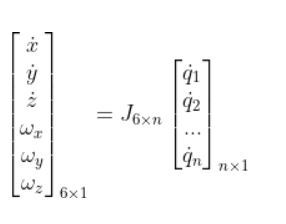

Ya se obtuvo el Jacobiano, ahora toca obtener el inverso.

Ahora para el punto 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

Como nuestro Jacobiano es cuadrado simplemente se encuentra el inverso del jacobiano de manera tradicional.

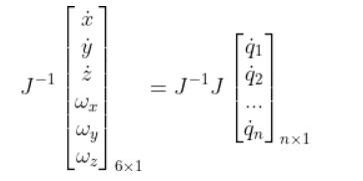

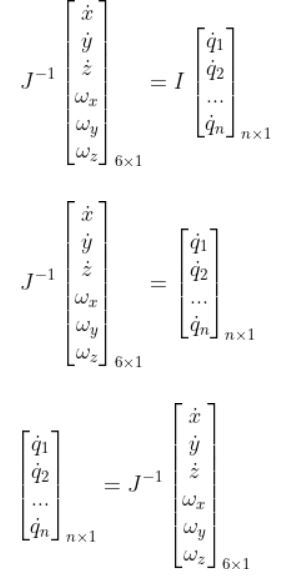

Jinv = pinv(J)

Jinv =    -0.0000    0.6203    0.0000   -0.1334   -0.0000    0.0000
    0.0851    0.0000   -0.9302   -0.0000   -0.0438   -0.0000
   -0.4918   -0.0000    0.9302   -0.0000    0.2528   -0.0000
   -0.0000    0.3102    0.0000   -0.0667    0.0000   -0.5000
   -0.0000    0.0000    0.0000   -1.0000    0.0000    0.0000
    0.0000    0.3102   -0.0000   -0.0667   -0.0000   -0.5000


Para obtener la respuesta con los valores propuestos luego hacemos:

V_H = [100;200;50]

V_H =    100
   200
    50


w_H = [5;10;-5]

w_H =      5
    10
    -5


vector = [V_H;w_H]

vector =    100
   200
    50
     5
    10
    -5


q_punto = Jinv*vector

q_punto =   123.4026
  -38.4380
   -0.1359
   64.2013
   -5.0000
   64.2013
